%
%newfile1 nominal 10V out 18vin 1.42Ain
%newfile2 nominal 10V out 17vin 1.55Ain
%newfile3 nominal 10V out 16vin 1.64Ain
%newfile4 nominal 10V out 15vin 1.73Ain

(6.3*10^-6)/(1/50000)

ans = 0.3150

(10^2/5)/(1.41*18)

ans = 0.7880


Lm=13.1uH
Leak=1uH
12.7uH
Vout=10;%v
Current=[1.42,1.53,1.63,1.73]
Voltage=[18,17,16,15]
%1.42A 9.97V

%Swiching
Ids=2.5;%A
Vds=18;%V
tr=900e-9;%Sec
tf=900e-9;%Sec
f=50000;%hz
D=0.35;
Psw=1/6*(Ids*Vds)*(tr+tf)*f

Psw = 0.6750

%Continus
Ron=0.034;
Vdson=0.08;%V
Ion=2.5

Ion = 2.5000

Pcds=Ion^2*Ron*(1-D)

Pcds = 0.1381

%Winding
Rw=0.1;
W=Ids^2*Rw

W = 0.6250

%Leakage
Lpl=2e-6

Lpl = 2.0000e-06

P=1/2*(Lpl*Ids^2)*f*D

P = 0.1094

Causes = ["MOSFET Switching Loss";"Continuous MOSFET loss";"Winding Loss";"Snubber and Clamp Loss"];
Values = [Psw; Pcds; W; P];
tbl = table(Causes,Values)

tbl = 4×2 table
             Causes             Values 
    ________________________    _______

    "MOSFET Switching Loss"        0.75
    "Continuous MOSFET loss"    0.13813
    "Winding Loss"                0.625
    "Snubber and Clamp Loss"    0.10938


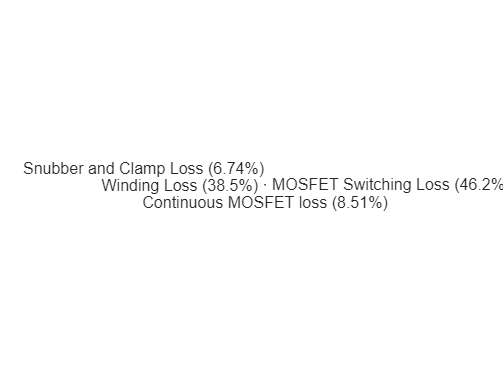

piechart(tbl,"Values","Causes")

efficiency=1-sum(Values)/10

efficiency = 0.8377